clear;
run("data/c3x7_s1602_l48.m");

% [U, S, V] = svd(T11)
% k1 = sqrt(S(1,1)) * U(:,1)



% assume T is your 3x3 complex matrix
T11 = (T11 + T11')/2;           % enforce Hermitian (conjugate transpose)
fprintf('Hermitian symmetry check: max abs(T-T'') = %g\n', max(abs(T11 - T11')));

Hermitian symmetry check: max abs(T-T') = 0
Hermitian symmetry check: max abs(T-T') = 0
Hermitian symmetry check: max abs(T-T') = 0



% eigen-decomposition (Hermitian aware)
[V,D] = eig(T11);
eigvals = diag(D);
[lambda1, idx] = max(real(eigvals));   % largest eigenvalue (real part)
lambda1 = max(lambda1, 0);              % clip tiny negatives
v1 = V(:, idx);

% reconstruct k1 (rank-1)
k1 = sqrt(lambda1) * v1   % note: global phase free

k1 =   -0.0292 - 0.0729i
   0.0090 + 0.0221i
   0.0073 + 0.0000i


v1

v1 =   -0.3538 - 0.8850i
   0.1097 + 0.2679i
   0.0884 + 0.0000i


k1*k1'

ans =    0.0062 + 0.0000i  -0.0019 - 0.0000i  -0.0002 - 0.0005i
  -0.0019 + 0.0000i   0.0006 + 0.0000i   0.0001 + 0.0002i
  -0.0002 + 0.0005i   0.0001 - 0.0002i   0.0001 + 0.0000i


% optional: fix global phase so first element is real nonnegative
phi = angle(k1(1))

phi = -1.9511

k1 = k1 * exp(-1i*phi)

k1 =    0.0786 + 0.0000i
  -0.0239 + 0.0002i
  -0.0027 + 0.0068i




% assume T is your 3x3 complex matrix
T22 = (T22 + T22')/2;           % enforce Hermitian (conjugate transpose)
fprintf('Hermitian symmetry check: max abs(T-T'') = %g\n', max(abs(T11 - T11')));

Hermitian symmetry check: max abs(T-T') = 0
Hermitian symmetry check: max abs(T-T') = 0
Hermitian symmetry check: max abs(T-T') = 0



% eigen-decomposition (Hermitian aware)
[V2,D2] = eig(T22);
eigvals = diag(D2);
[lambda2, idx] = max(real(eigvals));   % largest eigenvalue (real part)
lambda2 = max(lambda2, 0);              % clip tiny negatives
v2 = V2(:, idx);

% reconstruct k1 (rank-1)
k2 = sqrt(lambda2) * v2;   % note: global phase free
% optional: fix global phase so first element is real nonnegative
phi = angle(k2(1));
k2 = k2 * exp(-1i*phi);

% w1 = transpose([1/sqrt(2), -1/sqrt(2), 0]);
% w2 = transpose([1/sqrt(2), 1/sqrt(2), 0]);

w1 = transpose([0, 0, 1]);
w2 = w1;

num1 = w1' * O12 * w2

num1 = -3.9611e-05 - 2.4751e-04i

O12

O12 =   -0.0015 - 0.0060i   0.0000 + 0.0013i  -0.0001 + 0.0003i
   0.0004 + 0.0019i   0.0000 - 0.0006i   0.0001 - 0.0000i
   0.0005 + 0.0002i  -0.0002 - 0.0000i  -0.0000 - 0.0002i


O12_calc = (k1*k2')

O12_calc =    0.0067 + 0.0000i  -0.0015 - 0.0002i  -0.0003 - 0.0002i
  -0.0020 + 0.0000i   0.0005 + 0.0001i   0.0001 + 0.0000i
  -0.0002 + 0.0006i   0.0001 - 0.0001i   0.0000 - 0.0000i


%Calculate denomerator
denom1 = sqrt((w1' * T11 * w2) * (w1' * T22 * w2))

denom1 = 2.9335e-04

d=3

d = 3

num = w1'*k1*conj(w1'*k2)

num = 2.3867e-05 - 2.1684e-05i

denom=sqrt( (k1(d)*conj(k1(d))) * (k2(d)*conj(k2(d))) )

denom = 3.2246e-05


point = num/denom

point = 0.7402 - 0.6724i

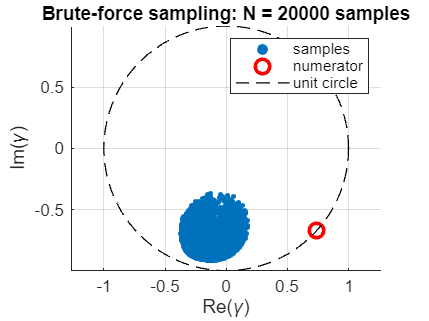


% Precompute for speed if needed
% We'll compute gamma(w) directly for many w vectors:
N = 20000; % number of random polarization samples (adjust)
gamma_vals = complex(zeros(N,1));
%3xN matrix
w_store = complex(zeros(3,N));

% sample w uniformly on complex unit sphere
%We dont need to check for repeated samples, because we are sampling from a
%continious distribution. So statistaclly we should not get identical
%samples.
for k = 1:N
    % randn(3,1) creates three random normally distrubited numbers, so that
    % we are uniform on the complex sphere.
    z = (randn(3,1) + 1i*randn(3,1));
    %Normalize
    w = z / norm(z);
    %Store the value
    w_store(:,k) = w;
    %Calculate numerator
    num = w' * O12 * w;
    %Calculate denomerator
    denom = sqrt((w' * T11 * w) * (w' * T22 * w));
    %calculate gamma and store it
    gamma_vals(k) = num / denom;
end

% --- Plot the brute-force sampled points ---
figure('Name','Brute-force coherence sampling','NumberTitle','off');
hold on;  % keep all plots in the same figure
axis equal; grid on;

% scatter plot of your samples
scatter(real(gamma_vals), imag(gamma_vals), 8, 'filled');

% plot special point numerator
plot(real(point), imag(point), 'ro', 'MarkerSize',8, 'LineWidth',2);

% draw unit circle for reference
th = linspace(0,2*pi,500);
plot(cos(th), sin(th), 'k--', 'LineWidth', 0.7);

% labels and title
xlabel('Re(\gamma)'); 
ylabel('Im(\gamma)');
title(sprintf('Brute-force sampling: N = %d samples', N));

% legend
legend('samples','numerator','unit circle');

hold off;  % optional, release hold